# Manipulator almost like MLS Example 3.2 p. 89

Consider the manipulator with 3 degrees of freedom as defined by three revolute joints, the twists axes of which are indicated by $\xi_1$, $\xi_2$ and $\xi_3$.  The figure shows the manipulator in the reference configuration.

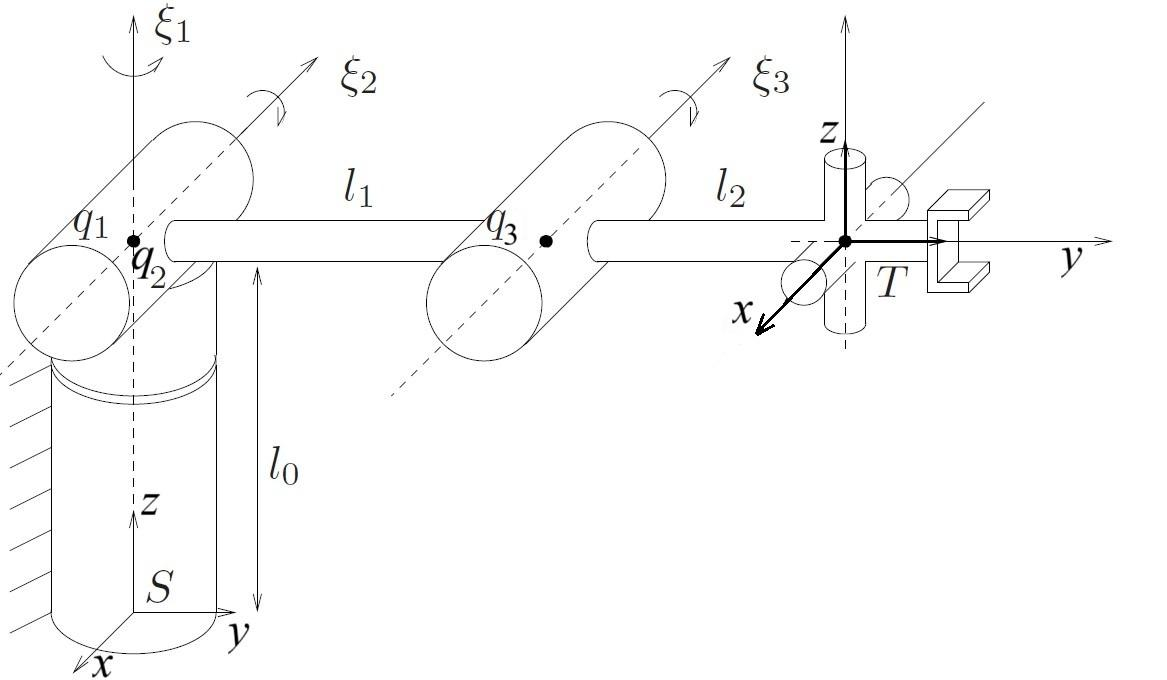

The lengths are as follows:

- $l_0 = 1.3$ m

- $l_1 = 1.1$ m

- $l_2 = 0.9$ m

This script should be expanded to solve the inverse kinematics problem, reading the desired configuration and the reference configuration from two Excel files.  The three twist angles $\theta_1$, $\theta_2$ and $\theta_3$ needs to be calculated.  The results should be checked by solving the forward kinematics problem with the product of exponentials formula, using the calculated values of $\theta_1$, $\theta_2$ and $\theta_3$ and confirming that the desired configuration matrix in the Excel file is in fact generated.

import robo.*
clearvars, clc

l0 = 1.3

l0 = 1.3000

l1 = 1.1

l1 = 1.1000

l2 = 0.9

l2 = 0.9000



gst0 = readmatrix('/Users/dixiao/LAST1/大四下/Nico_Robo_control/Codes/Tutorial_Apr.29/April_29_gst0.xlsx')

gst0 =     1.0000         0         0         0
         0    1.0000         0    2.0000
         0         0    1.0000    1.3000
         0         0         0    1.0000


gd   = readmatrix('/Users/dixiao/LAST1/大四下/Nico_Robo_control/Codes/Tutorial_Apr.29/April_29_gst.xlsx')

gd =     0.7071   -0.7071         0   -1.2576
    0.7071    0.7071    0.0000    1.2576
         0         0    1.0000    0.6380
         0         0         0    1.0000



omega1 = [0;0;1];
omega2 = [-1;0;0];
omega3 = omega2;
q1 = [0;0;l0];
q2 = [0;0;l0];
q3 = [0;l1;l0];

xi1 = [-hatm(omega1)*q1;omega1];
xi2 = [-hatm(omega2)*q2;omega2];
xi3 = [-hatm(omega3)*q3;omega3];

g1 = gd/gst0

g1 =     0.7071   -0.7071         0    0.1566
    0.7071    0.7071    0.0000   -0.1566
         0         0    1.0000   -0.6620
         0         0         0    1.0000


% 用用尼的办法吧，先把三轴换成2轴去接PK2问题
p_3 = [q3;1] %一定是4 x 1矩阵

p_3 =          0
    1.1000
    1.3000
    1.0000



qt = g1*p_3;

[theta1,theta2] = PK2(xi1,xi2,p_3,qt);
theta1_deg_1 = rad2deg(theta1(1))

theta1_deg_1 = 45.0000

theta2_deg_1 = rad2deg(theta2(1))

theta2_deg_1 = 37.0000

%========
theta1_deg_2 = rad2deg(theta1(2))

theta1_deg_2 = -135.0000

theta2_deg_2 = rad2deg(theta2(2))

theta2_deg_2 = 143

%===================================

%第一组解

Rt_1 = gtwist(-xi2,theta2(1)) * gtwist(-xi1,theta1(1)) * g1

Rt_1 =     1.0000   -0.0000    0.0000    0.0000
    0.0000    0.7986   -0.6018    1.0039
    0.0000    0.6018    0.7986   -0.4002
         0         0         0    1.0000


%接下来只剩一个theta3没接了，直接用PK1解

%注意PK1 这里的p选择点，不能是轴上的点，必须是轴外的，可以任意点
pt1 = [q1;1]

pt1 =          0
         0
    1.3000
    1.0000


qt1 = Rt_1 * pt1;

theta3_1 = rad2deg(PK1(xi3,pt1,qt1))

theta3_1 = -37





%第二组解

Rt_2 = gtwist(-xi2,theta2(2)) * gtwist(-xi1,theta1(2)) * g1

Rt_2 =    -1.0000    0.0000   -0.0000   -0.0000
    0.0000    0.7986   -0.6018    1.0039
   -0.0000   -0.6018   -0.7986    3.0002
         0         0         0    1.0000



pt2 = [[0;1;1];1]

pt2 =      0
     1
     1
     1


qt2 = Rt_2 * pt2;

theta3_2 = rad2deg(PK1(xi3,pt2,qt2))

theta3_2 = -179.8699